# Manipulate the Equations Of Motion

Plug in Numerical Parameters and Linearize the System About the Unstable Equilibrium Point

cd 'F:\Sourcetree Repos\Matlab Personal\Ball Plate Thesis'
addpath('Kinematics')
addpath('Kinetics')

supressed_print= evalc('run Ball_Plate_Kinetics_Newton_Euler.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

## Best Current Estimates of Numerical System Parameters

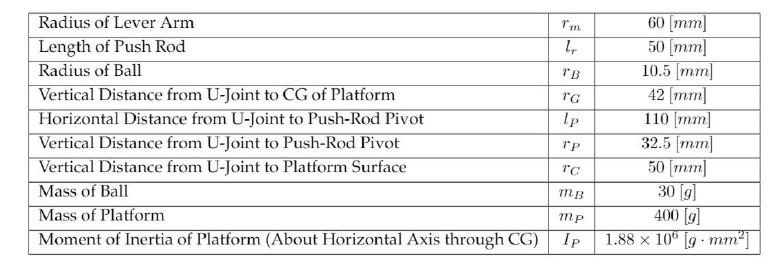

Length Related System Parameters DIAGRAMS HERE WOULD BE USEFUL

w - width of plate

hPc - Height from center of u-joint to point Pc (in the z-direction of the S2 frame - constant)

z_p - height of the plate's C.O.M with respect to the frame origins at the center of the u-joint

L_carm - length of motor mechanism crank arm

L_crod - length of motor mechanism connecting rod

Variables related to Mass and Geometry of the Ball

I_b - mass moment of inertia of the ball (spherically symmetric)

I_p_xx - x direction mass moment of inertia of plate (principle axis)

I_pyy - y direction mass moment of inertia of plate (principle axis)

I_pzz - z direction mass moment of inertia of plate (principle axis)

m_b - mass of the ball

m_p - mass of the plate

r_b - radius of the ball

rB = .0105; %[m]
rG = .042; %[m]
rC = .050; %[m]
mB = .030; %[kg]
mP = .400; %[kg]
IP = 1.88e6*(1/1000)*(1/1000)^2; %[kg*m^2]
IB = (2/5)*mB*rB^2;%ball inertia [kg-m^2] 
g_num = 9.81; %[m/s^2]
%IPz = 0;%For some reason

Num_Params = [rB  rC+rB mB mP IP IB g_num rG 0 0];
Sym_Params = [r_b z_b m_b m_p I_p__xx I_b g z_p psi_dot_z psi_z];

Substitute Known Numerical Parameters Into Symbolic EOMs

NumEOMs = subs(SolvedEOMs, Sym_Params, Num_Params);

%%%Augment the EOMs with the Lower Order Derivative Relationships Necessary to Put the System into State Space Form

% %state vector: [x_dot, y_dot, beta_dot, gamma_dot]
% LOT_EOMs = [x_dot == x_dot
%             y_dot == y_dot
%             beta_dot == beta_dot]; 

Take the Jacobian of the Right Hand Side of the EOMs. 

J(stateVec) = jacobian(rhs(NumEOMs), stateVec)


Form the State Space Model $\dot{x} = Ax$ where $x = [x ~y ~\beta ~\gamma~\dot{x}~\dot{y}~\dot{\beta}~\dot{\gamma}]^T$

A(stateVec) = [zeros(4),eye(4);J];
A_OpP = A(0,0,0,0,0,0,0,0)

$$A\_OpP = \left[\begin{array}{cccccccc} 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ -5.2170 & 0 & 4.0111 & 0 & 0 & 0 & 0 & 0\\ 0 & -5.2170 & 0 & -4.0111 & 0 & 0 & 0 & 0\\ 112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0 & 0\\ 0 & -112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0 \end{array}\right]$$

Results: 


$$\left\lbrack \begin{array}{c}

\dot{x}\\ \dot{y}\\ \dot{\beta}\\ \dot{\gamma}\\ 
\ddot{x}\\ \ddot{y}\\ \ddot{\beta}\\ \ddot{\gamma}

\end{array}\right\rbrack 

=

\left\lbrack \begin{array}{cccccccc}
0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\
-5.2170 & 0 & 4.0111 & 0 & 0 & 0 & 0 & 0\\
0 & -5.2170 & 0 & -4.0111 & 0 & 0 & 0 & 0\\
112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0 & 0\\
0 & -112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

x\\ y\\ \beta\\ \gamma\\ 
\dot{x}\\ \dot{y}\\ \dot{\beta}\\ \dot{\gamma}

\end{array}\right\rbrack$$


Show decoupled system

A_uncpld = [A_OpP(:,1),A_OpP(:,5),A_OpP(:,3),A_OpP(:,7),A_OpP(:,2),A_OpP(:,6),A_OpP(:,4),A_OpP(:,8)];
A_uncpld = [A_uncpld(1,:);A_uncpld(5,:);A_uncpld(3,:);A_uncpld(7,:);A_uncpld(2,:);A_uncpld(6,:);A_uncpld(4,:);A_uncpld(8,:)]

$$A\_uncpld = \left[\begin{array}{cccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ -5.2170 & 0 & 4.0111 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$


$$\left\lbrack \begin{array}{c}

\dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\

\dot{y}\\ \ddot{y}\\ \dot{\gamma}\\  \ddot{\gamma}

\end{array}\right\rbrack

=

\left\lbrack \begin{array}{cccccccc}
0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\
-5.2170 & 0 & 4.0111 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\
112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & -5.2170 & 0 & -4.0111 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & -112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

x\\ \dot{x}\\ \beta\\ \dot{\beta}\\

y\\ \dot{y}\\ \gamma\\  \dot{\gamma}

\end{array}\right\rbrack$$
